# Calculation of delay

close all; clear; clc;
list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end
clear list_factory index_interpreter default_name i;

% Add paths
% addpath(genpath('Data'));
addpath(genpath('Data_v2'));

% Settings
SETTINGS.titleFS    = 18;
SETTINGS.subtitleFS = 15;
SETTINGS.labelFS    = 12;

load('Latency.mat');


## Measurement 1

CurrentMeasurement = measurementData;

Measurement taken at:

display(CurrentMeasurement.TimeOfCapture)

  datetime

   08-May-2023 08:54:54 UTC+02:00



Device (driver):

display(CurrentMeasurement.Device)

    "FL Studio ASIO"



Sample rate:

fs = CurrentMeasurement.SampleRate;
display(fs)

fs = 44100

Samples per frame:

display(CurrentMeasurement.SamplesPerFrame)

        1024



Player and recorder channels (amount):

display(CurrentMeasurement.PlayerChannels)

  1×1 cell array

    {[1]}



display(CurrentMeasurement.RecorderChannel)

     1



Method used:

display(CurrentMeasurement.Method)

    "Swept Sine"



Number of runs:

display(CurrentMeasurement.NumRuns)

     1



Excitation level [dB]

display(CurrentMeasurement.ExcitationLevel)

    -6



## Signal plots

input       = CurrentMeasurement.RawAudioData.ExcitationSignal;
recorded    = CurrentMeasurement.RawAudioData.RecordedSignal;
t           = (0:size(input, 1)-1)'/fs;

The recorded signal plotted:

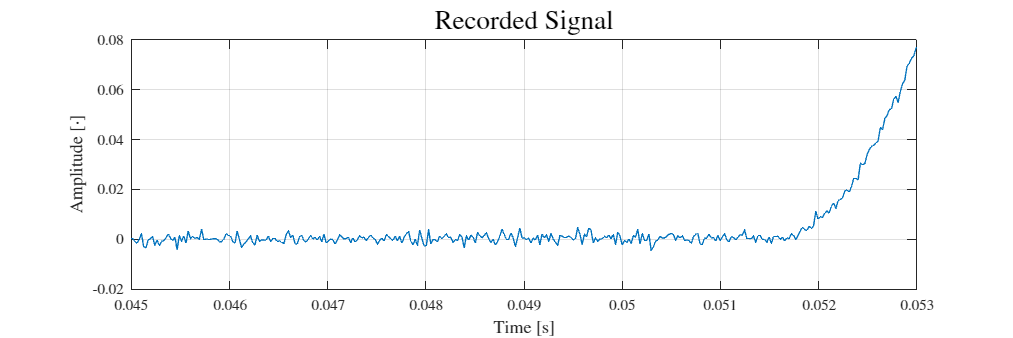

f = figure('Position', [10 10 900 300]);
plot(t, recorded(:, 1));
grid on;
title('Recorded Signal', 'FontSize', SETTINGS.titleFS);
xlim([0.045 0.053]);
xlabel('Time $[\mathrm{s}]$', 'FontSize', SETTINGS.labelFS);
ylabel('Amplitude $[\cdot]$', 'FontSize', SETTINGS.labelFS);
exportgraphics(f, 'Figures/Delay.pdf', 'Resolution', 300);